# 034IN -FONDAMENTI DI AUTOMATICA - FUNDAMENTALS OF AUTOMATIC CONTROL -  A.Y. 2024/2025

# Full Examination

**June 20, 2025**

# Part 1 - MATLAB Grader - Exercise 2

##                   From Ordinary Differential Equations to State-Space Realisation                                 

### Introduction: Modelling and Analysing a Heat Process

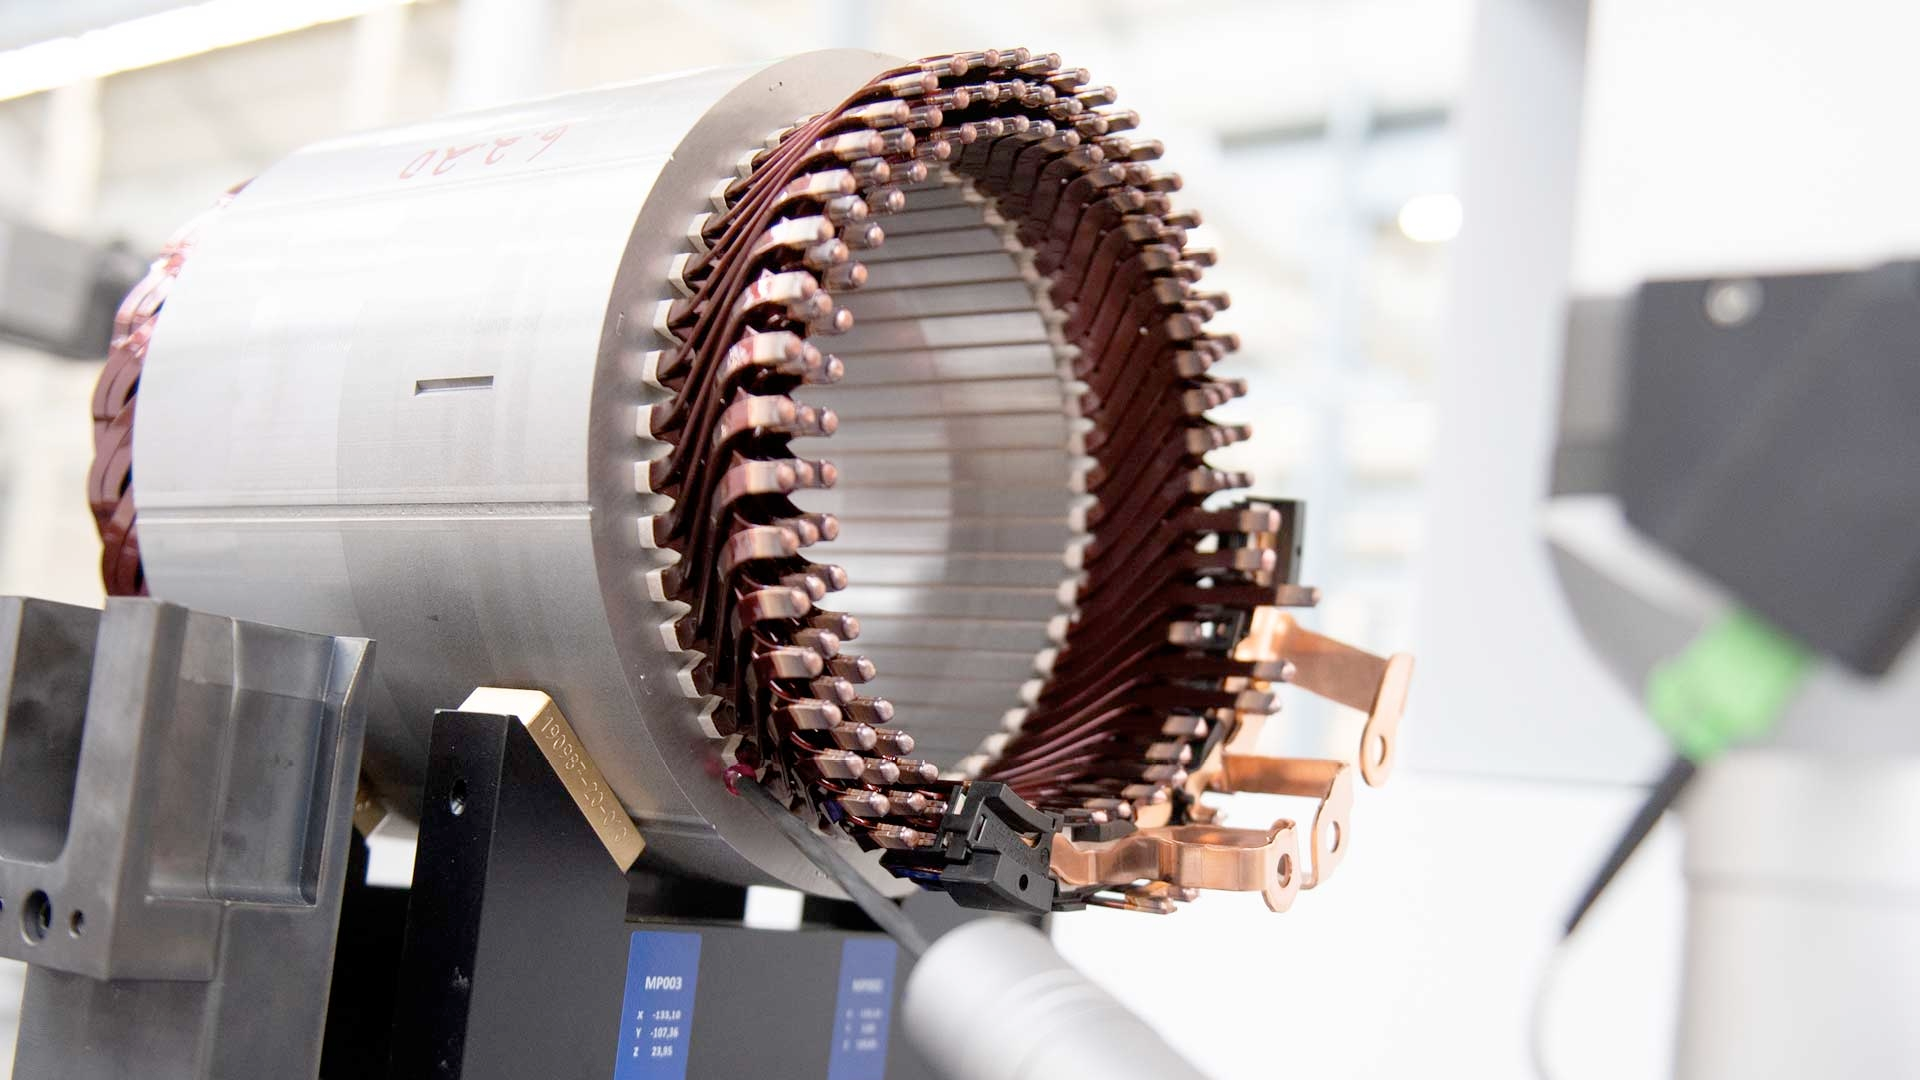

**Fig. 1: Example of an electric motor.**

You can determine how temperature varies in various types of electrical equipment by observing their warming behavior. For instance, this model allows us to examine the warming process in the slots of electrical machines, where copper windings are situated within iron slots.

Let us analyse the heat process of a system consisting of two heat sources. The arrangement is shown in Fig. 2

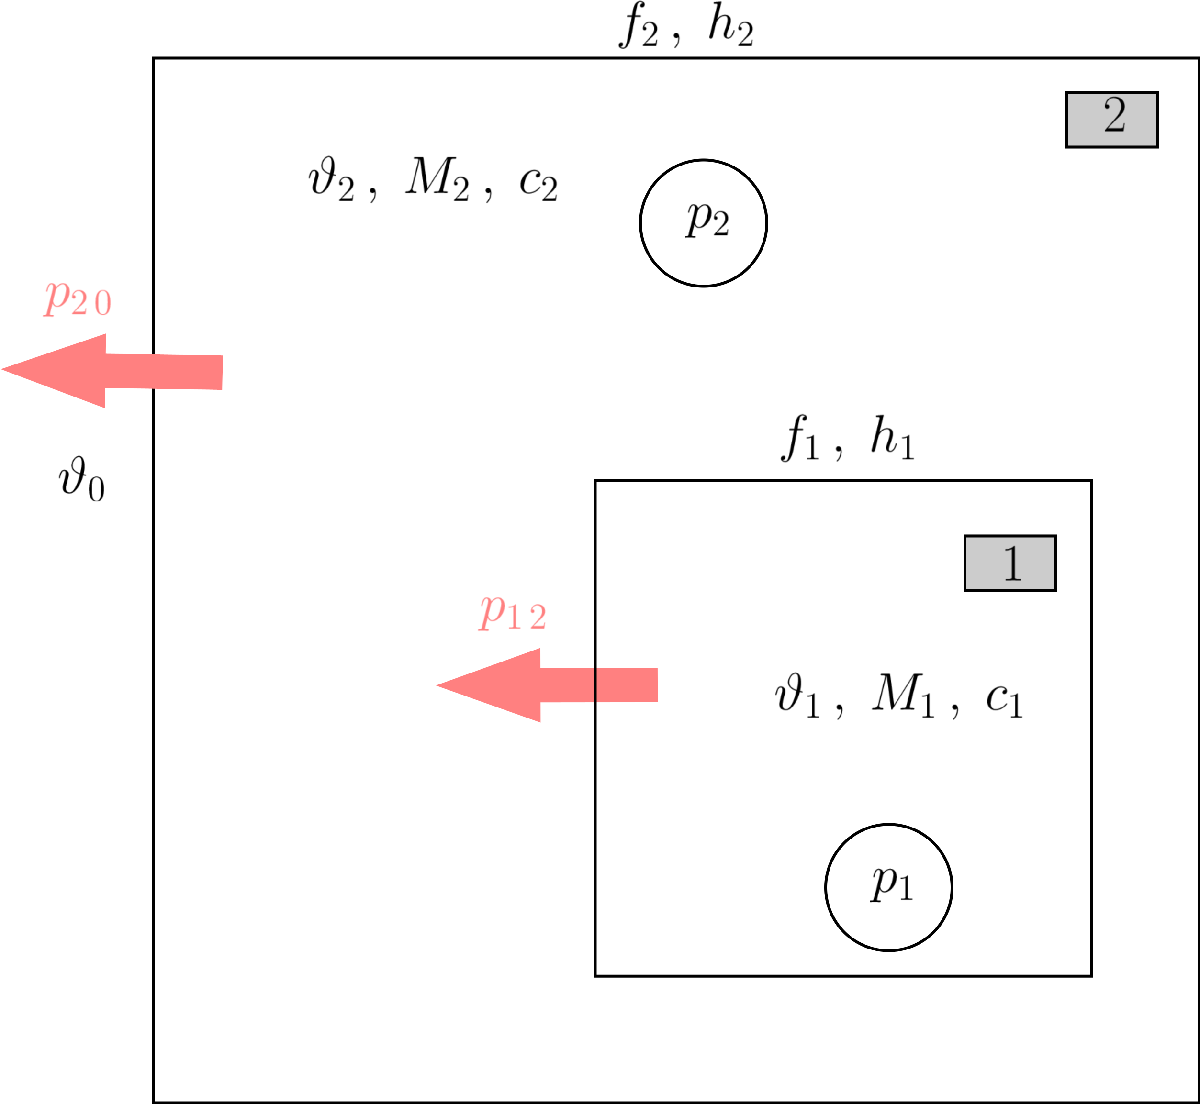

**Fig. 2: A heat process.**

In the body of mass $M_2$ and specific heat $c_2$, power $p_2$ is converted to heat. This body encloses the body of mass $M_1$and specific heat $c_1$, where the heat power is $p_1$. The surfaces where the two bodies are in contact with each other and with the external environment are $f_1$ and $f_2$, with heat transfer coefficients $h_1$ and $h_2$, respectively. 

Let us determine the change of temperatures $\vartheta_1$ and $\vartheta_2$ in the two bodies after switching on the heat generation, supposing that earlier the temperature of the system was equal to the environmental temperature $\vartheta_0$. So the input signals of the system are the heating powers $p_1$ and $p_2$, the disturbance is the environmental temperature $\vartheta_0$, and the output signals are $\vartheta_1$ and $\vartheta_2$, the temperatures of the two bodies.

The behaviour of the system can be described as follows


$$\left\{\begin{array}{rcl}
\dot{\vartheta}_1(t) &=& -\frac{1}{G_1 R_1} \vartheta_1(t) + \frac{1}{G_1 R_1} \vartheta_2(t) + \frac{1}{G_1} p_1(t) \\
\dot{\vartheta}_2(t) &=& \frac{1}{G_2 R_1} \vartheta_1(t) - \frac{1}{G_2}\,\frac{R_1+R_2}{R_1\,R_2} \vartheta_2(t) + \frac{1}{G_2} p_2(t) + \frac{1}{G_2 R_2} \vartheta_0
\end{array} \right. \qquad (*)$$


where


$$R_1 = \frac{1}{h_1 f_1} \,,\; R_2 = \frac{1}{h_2 f_2}\,,\; G_1 = M_1 c_1\,,\; G_2 = M_2 c_2$$


## Assignment

Your code shall:

- Determine a state-space description for the LTI system described by Eq. $(*)$. The inputs, outputs and state variables of the system are as follows:


$$\begin{array}{rcl}
\text{Inputs} &:& u_1(t)= p_1(t)\,,\; u_2(t) = p_2(t)\,,\; u_3(t) = \vartheta_0(t) \\
\text{Outputs} &:& y_1(t) = \vartheta_1(t)\,,\; y_2(t) = \vartheta_2(t) \\
\text{State variables} &:& x_1(t) = \vartheta_1(t)\,,\; x_2(t) = \vartheta_2(t)
\end{array}$$


- Assume the following numeric values for the parameters:


$$R_1 =1\,,\; R_2 = 1\,,\; G_1=1\,,\; G_2 = 5$$


- Assign the matrices $A\,,\;B\,,\;C\,,\;D$ of the state equations respectively to the **numeric** **variables** `numA`, `numB`, `numC`, and `numD`.

- Calculate the characteristic polynomial of the LTI system as a numeric array, using the MATLAB command `charpoly`. Save the resulting array in the numeric variable  `polyA`. [The documentation of the command `charpoly` is available [here](https://it.mathworks.com/help/releases/R2024b/symbolic/sym.charpoly.html?overload=sym%2Fcharpoly+true&searchPort=50842)].

- Compute the eigenvalues of the $A$ matrix and save the result in the **numeric** array **eigA**.

- Assume as initial state the vector $x(0) = \big[ \vartheta_1(0)\,,\;\vartheta_2(0) \big]^{\top} = \big[ 23,4^{\circ}\,,\; 24.6^{\circ} \big]^{\top} $ and the inputs


$$u_1(t) = 100\cdot \mathbf{1}(t)\,,\; u_2(t) = 250\cdot \mathbf{1}(t)\,,\; u_3(t) = 20\cdot \mathbf{1}(t)$$


            where, as usual, $\mathbf{1}(t)$ is the unit step function.

- Generate an array of time instants $t_k \in \big[0\,,\;5 \big]$,  with $t_k = k \cdot \Delta\,,\; \Delta = 0.01\;\text{sec.}\,,\; k= 0,\,1,\,\ldots$

- Properly using the command `lsim()`, calculate the state movement, starting from the given initial state $x(0)$, and corresponding to the assigned inputs. Save the result in the **numeric** **variable** **Xmov**. 

## Solution

% --- the parameters ---
R1 = 1;
R2 = 1;
G1 = 1; 
G2 = 5;
% --- the parameters ---


% ------ 1st, 2nd & 3rd bullet point ------
numA = [-1/(G1*R1),  1/(G1*R1);
         1/(G2*R1),  -(1/G2)*(R1+R2)/(R1*R2)];
numB = [1/G1,  0,    0;
          0,  1/G2,  1/(G2*R2)];
numC = eye(2);
numD = zeros(2,3);
% ------ 1st, 2nd & 3rd bullet point ------

% -------- the 4th bullet point --------
polyA = charpoly(numA)

polyA =     1.0000    1.4000    0.2000


% let's compute the eigenvalues in an alternative way
roots(polyA)

ans =    -1.2385
   -0.1615


% -------- the 4th bullet point --------

% ---- the 5th bullet point ----
eigA = eig(numA)

eigA =    -1.2385
   -0.1615


% ---- the 5th bullet point ----


% -------- the 6th & 7th bullet points --------
Tset = (0:0.01:5);
x0 = [23.4; 24.6];
U1 = 100 .*ones(size(Tset));
U2 = 250 .* ones(size(Tset));
U3 = 20 .*ones(size(Tset));
% -------- the 6th & 7th bullet points --------


% ---- the 8th bullet point ----
sysC = ss(numA, numB, numC, numD);

[Ymov, ~, Xmov] = lsim(sysC, [U1; U2; U3], Tset,  x0);
% ---- the 8th bullet point ----


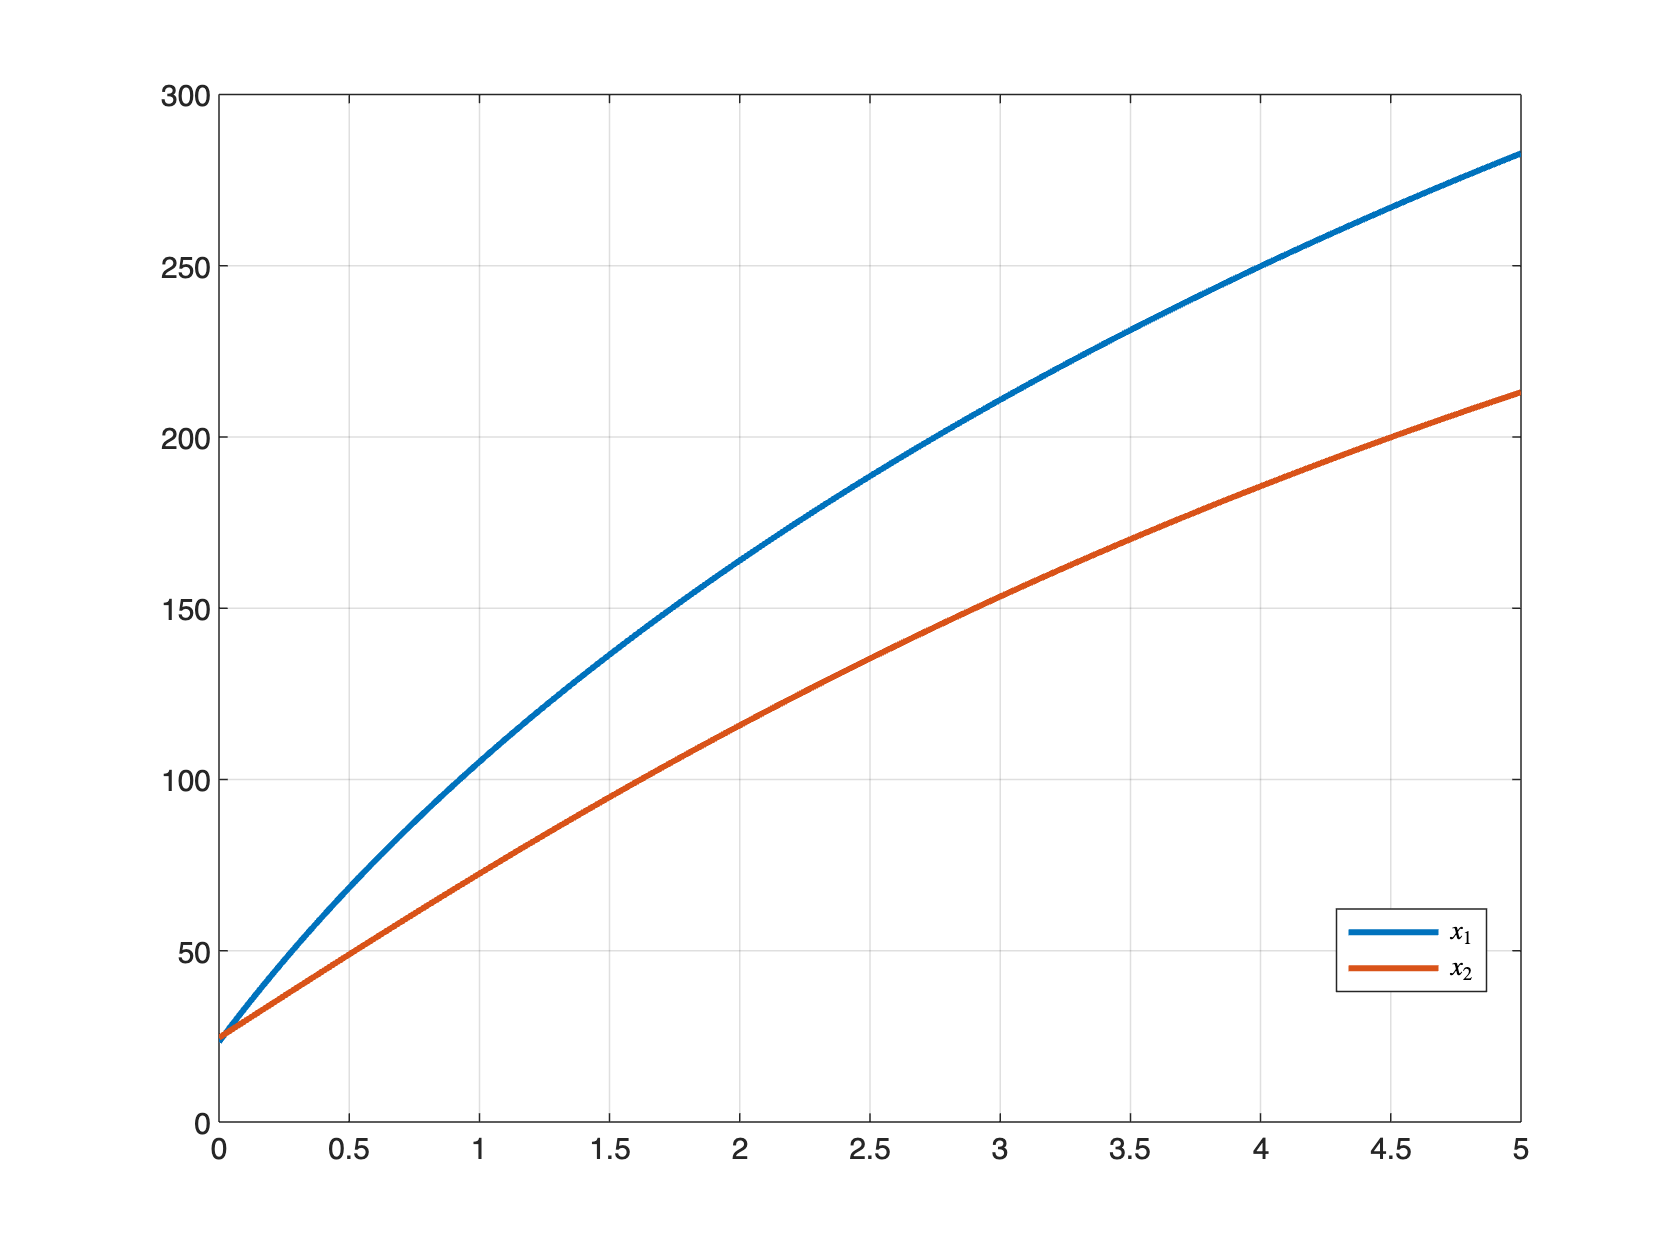

% ==== NOT REQUIRED ====
figure;
plot(Tset, Xmov, 'LineWidth', 2)
grid on;
legend('$x_1$', '$x_2$', 'Interpreter', 'latex','Location', 'best')

% ==== NOT REQUIRED ====


% ========== END OF LIVE SCRIPT ==========